## Treino para teste PL3

#### 1. Mostre que as seguintes decomposições de um sinal periódico (de frequência 𝜔0) em Série de Fourier são equivalentes: 

#### 𝑥(𝑡) = ∑𝐴𝑘 cos(𝑘𝜔0𝑡 + 𝜑𝑘 ) 𝐾 𝑘=1 = ∑𝑎𝑘 cos(𝑘𝜔0𝑡) 𝐾 𝑘=1 + ∑𝑏𝑘 sin(𝑘𝜔0𝑡) 𝐾 𝑘=1 

%não

#### 2. Determine as expressões de 𝑎𝑘 e 𝑏𝑘 correspondentes à representação do seguinte sinal em Série de Fourier: 

%ak = 0;
%bk = cos(2.*k)./pi - (2.*cos(pi*k))./pi.*k + 1./(pi.*k);

#### 3. Desenvolva uma função em MATLAB que produza o sinal resultante da série de Fourier que é gerada a partir da seguinte informação: 

#### - 𝑇𝑎: Período de amostragem, em segundos; 

#### - 𝑓0: Frequência do sinal composto, em Hz; 

#### - 𝑁𝑝: Número de períodos a considerar para o sinal resultante; 

#### - 𝑎𝑘: Vetor (𝐾x1) com os valores de 𝑎𝑘 da série; 

#### - 𝑏𝑘: Vetor (𝐾x1) com os valores de 𝑏𝑘 da série. 

#### Experimente esta função para os valores dos coeficientes da pergunta 2, e veja como progressivamente o resultado se vai aproximando do sinal representado nessa pergunta.

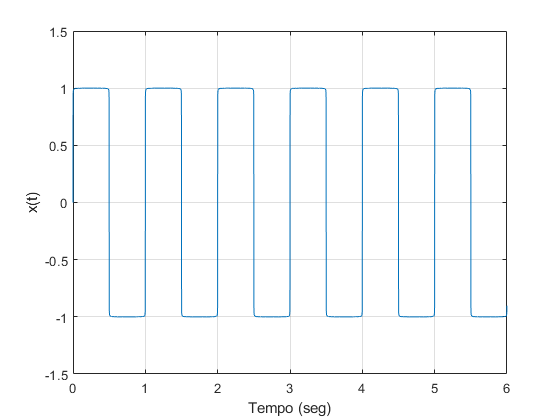

k = (1:998);
Ta = 0.001;
T = 1;
f0 = 1/T;
Np = 6;
ak = zeros(size(k));
bk = cos(2*pi.*k)./(pi.*k) - (2.*cos(pi.*k))./(pi.*k) + 1./(pi.*k);
[sinal,tempo] = Sinal_Fourier(Ta,f0,Np,ak,bk);
plot(tempo, sinal);
xlabel("Tempo (seg)");
ylabel("x(t)");
grid;

#### 4. Use a função desenvolvida na pergunta 3 para verificar que um sinal periódico par (i.e., com simetria relativamente ao eixo das ordenadas) tem todos os coeficientes 𝑏𝑘 nulos, e que um sinal periódico ímpar (i.e., simétrico relativamente à origem do referencial) tem todos os coeficientes 𝑎𝑘 nulos. 

#### 5. Desenvolva uma função em MATLAB que calcule os coeficientes 𝑎𝑘 e 𝑏𝑘 de um sinal periódico 𝑥(𝑛). Essa função deverá receber como argumentos de entrada: 

#### - 𝑇𝑎: Período de amostragem, em segundos; 

#### - 𝑇0: Período do sinal, em segundos; 

#### - 𝑥: Vetor (𝑁x1) com as amostras sucessivas do sinal a decompor (deverá ser passado um número inteiro de períodos deste sinal, não devendo o último período ficar truncado); 

#### - 𝐾: Número de harmónicas a considerar na decomposição

Coeficientes(Ta,T0,x,K);

#### 6. Teste a função desenvolvida na pergunta 5 para decompor os seguintes sinais (e, depois, reconstrua estes sinais usando a função desenvolvida na pergunta 3):